#  Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

The shell is supported at the two opposite edges aligned along the y-axis, and we place 2 control forces at the Node A and Node B, respectively, as seen in the following figure. The forces are illustrated as red solid arrows.

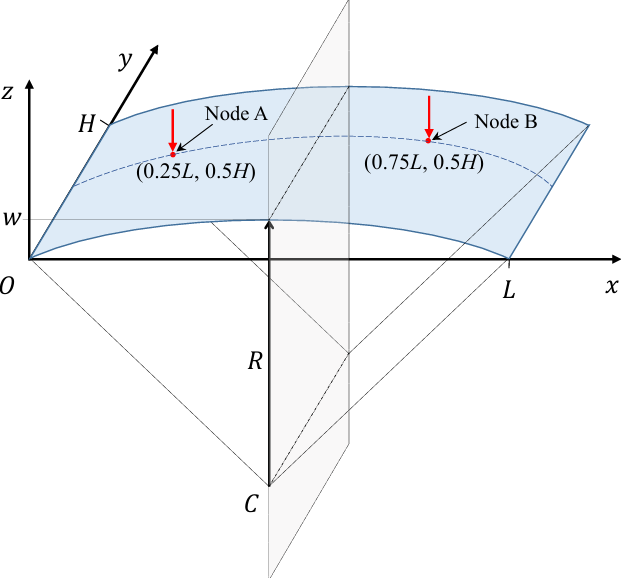

**system parameters**

clc; clear all;
nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)

## Model Setup

Building FE model


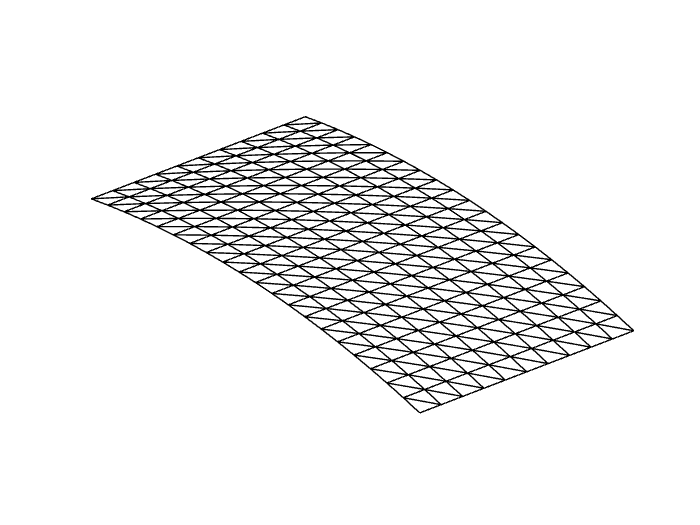

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  显示 所有属性

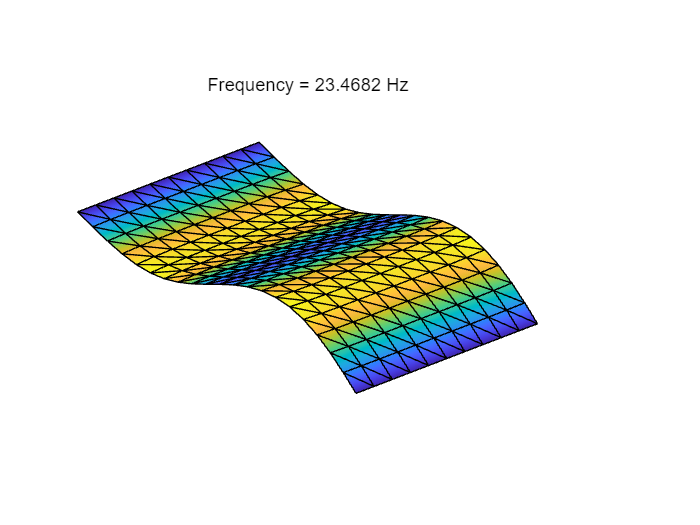

Using Rayleigh damping
damping coefficient
    0.0000
    0.4022
Assembling external force vector
outnodes
   171    61
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:10


[M,C,K,fnl,f_0,outdof] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',100,'Nmax',20,'notation','multiindex')

We assume that there is no external excitation but control inputs

Bext     = zeros(n,2); Bext(outdof(1),1)=1; Bext(outdof(2),2)=1; 
epsilon = 0.1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 100 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.269789e-03
modal damping ratio for 4 mode is 2.721500e-03
modal damping ratio for 5 mode is 2.909530e-03
modal damping ratio for 6 mode is 3.773001e-03
modal damping ratio for 7 mode is 3.967986e-03
modal damping ratio for 8 mode is 4.154750e-03
modal damping ratio for 9 mode is 4.434185e-03
modal damping ratio for 10 mode is 4.442169e-03
modal damping ratio for 11 mode is 4.647125e-03
modal damping ratio for 12 mode is 4.776358e-03
modal damping ratio for 13 mode is 4.925215e-03
modal damping ratio for 14 mode is 5.301612e-03
modal damping ratio for 15 mode is 5.947012e-03
modal damping ratio for 16 mode is 5.970063e-03
modal damping rat

## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     4     0
     5     1
     6     2
     7     3
     0     4
     1     5
     2     6
     3     7
     7     0
     8     1
     0     7
     1     8
     8     0
     9     1
     0     8
     1     9
    10     0
     0    10
    10     0
     0    10
These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *
  -0.0017 + 0.5960i
  -0.0017 + 0.5960i
  -0.0017 + 0.5960i
  -0.0017 + 0.5960i
  -0.0017 - 0.5960i
  -0.0017 - 0.5960i
  -0.0017 - 0.5960i
  -0.0017 - 0.5960i
  -0.0048 + 1.0316i
  -0.0048 + 1.0316i
  -0.0048 - 1.0316i
  -0.0048 - 1.0316i
  -0.0063 + 1.1893i
  -0.0063 + 1.1893i
  -0.0063 - 1.1893i
  -0.0063 - 1.1893i
  -0.0095 + 1.4641i
  -0.0095 - 1.4641i
  -0.0096 + 1.4759i
  -0.0096 - 1.4759i
sigma_out = 916
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
   

order = 5;
% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.27E+01 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.37E+01 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.48E+01 MB
Manifold computation time at order 5 = 00:00:01
Estimated memory usage at order  5 = 1.67E+01 MB


auData = construct_autoData(DS, masterModes, R_0);   % use linear_spectral result   

## Linear model order reduction analysis

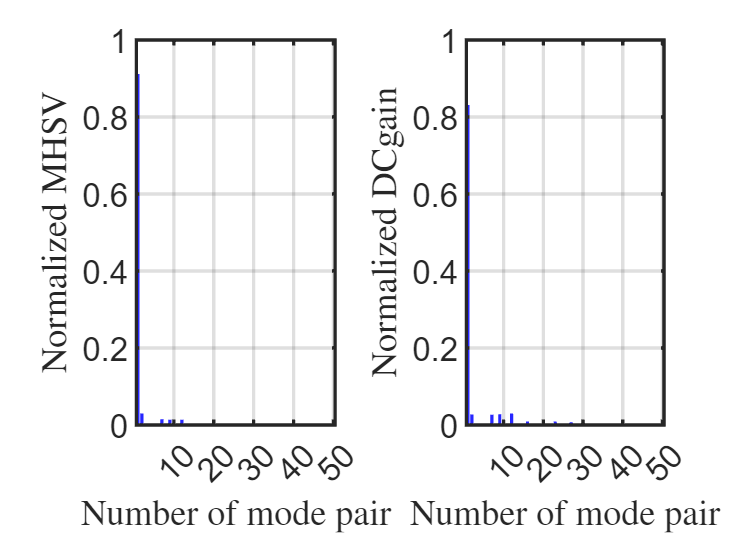

MHSV sum of the first 2 pairs
    0.9415
DCgain sum of the first 2 pairs
    0.8582


res = Linear_MOR(DS,50);

## Free Vibration

% initial condition
z0 = load('load400.mat','z0'); z0 = z0.z0;
tf     = 0.2; nsteps = 500;

t0 = 0; t1 =tf;
om = 2*pi/t1;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99999
Iteration 1, Residual norm = 0.23367
Iteration 2, Residual norm = 0.00017361
Iteration 3, Residual norm = 2.1819e-11
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99992
Iteration 1, Residual norm = 0.091445
Iteration 2, Residual norm = 1.0657e-05
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99989
Iteration 1, Residual norm = 0.060965
Iteration 2, Residual norm = 7.2652e-06
time integration completed: 0.6%
Iteration 0, Residual norm = 0.99988
Iteration 1, Residual norm = 0.055823
Iteration 2, Residual norm = 2.008e-05
time integration completed: 0.8%
Iteration 0, Residual norm = 0.99989
Iteration 1, Residual norm = 0.037383
Iteration 2, Residual norm = 1.8547e-05
time integration completed: 1%
Iteration 0, Residual norm = 0.99986
Iteration 1, Residual norm = 0.046821
Iteration 2, Residual norm = 7.475e-06
time integration completed: 1.2%
Iteration 0, Residual norm = 0.99987
Iteration 1, Residual norm = 0.037195
It

## Closed loop control with 2 receding horizons

**Time interval - 1**

% control parameters
cont   = struct();
cont.Q    = 1e4*eye(2*n);
cont.Rhat = 0.1*eye(2);
cont.Mhat = 0e1*eye(2*n); 

t0 = 0; 
t1 = 0.1;
tspan1 = linspace(t0,t1,nsteps);
traj1 = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,masterModes,1:2,cont);

pl
   0.0994 - 0.0002i
   0.0994 + 0.0002i
p0
   0.0994 - 0.0002i
   0.0994 + 0.0002i
Time for backward simulation of Riccati ODE is 7.819770e-02
Time for backward simulation of compensated ODE is 3.377529e-01
历时 0.304325 秒。
Time for forward simulation of ODEs for modal coordinates is 3.130167e-01


ufun1 = @(t) transpose(interp1(traj1.time,traj1.ut',t,'linear','extrap'));
set(DS,'u',ufun1);
[tfull1, xfull1,x1f,xt1] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99842
Iteration 1, Residual norm = 0.0052455
Iteration 2, Residual norm = 2.4241e-08
time integration completed: 0.2%
Iteration 0, Residual norm = 0.99868
Iteration 1, Residual norm = 0.0066024
Iteration 2, Residual norm = 2.5575e-08
time integration completed: 0.4%
Iteration 0, Residual norm = 0.99912
Iteration 1, Residual norm = 0.0042113
Iteration 2, Residual norm = 1.0068e-08
time integration completed: 0.6%
Iteration 0, Residual norm = 0.99807
Iteration 1, Residual norm = 0.0041626
Iteration 2, Residual norm = 8.5619e-10
time integration completed: 0.8%
Iteration 0, Residual norm = 0.99675
Iteration 1, Residual norm = 0.0028333
Iteration 2, Residual norm = 2.4948e-10
time integration completed: 1%
Iteration 0, Residual norm = 0.99491
Iteration 1, Residual norm = 0.002399
Iteration 2, Residual norm = 2.7445e-10
time integration completed: 1.2%
Iteration 0, Residual norm = 0.99214
Iteration 1, Residual norm = 0.0026372
Iteration 2, Residual norm = 4.54

**Time interval - 2**

t2 = 0.2;
tspan2 = linspace(t1,t2,nsteps);
traj2  = LQR_closed_loop(DS,x1f','linear',tspan2,auData,W_0,masterModes,1:2,cont);

pl
  -0.0118 + 0.0079i
  -0.0118 - 0.0079i
p0
  -0.0118 + 0.0079i
  -0.0118 - 0.0079i
Time for backward simulation of Riccati ODE is 4.239390e-02
Time for backward simulation of compensated ODE is 3.224287e-01
历时 0.313752 秒。
Time for forward simulation of ODEs for modal coordinates is 3.220181e-01


ufun2 = @(t) transpose(interp1(traj2.time,traj2.ut',t,'linear','extrap'));
set(DS,'u',ufun2);
[tfull2, xfull2,x2f,xt2] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',x1f','ts',t1);

Iteration 0, Residual norm = 0.89356
Iteration 1, Residual norm = 4.0137e-05
time integration completed: 50.1%
Iteration 0, Residual norm = 0.91541
Iteration 1, Residual norm = 4.3342e-05
time integration completed: 50.2%
Iteration 0, Residual norm = 0.90603
Iteration 1, Residual norm = 5.5834e-05
Iteration 2, Residual norm = 7.1849e-13
time integration completed: 50.3%
Iteration 0, Residual norm = 0.90418
Iteration 1, Residual norm = 6.3826e-05
Iteration 2, Residual norm = 6.4839e-13
time integration completed: 50.4%
Iteration 0, Residual norm = 0.90288
Iteration 1, Residual norm = 6.3097e-05
Iteration 2, Residual norm = 6.2344e-13
time integration completed: 50.5%
Iteration 0, Residual norm = 0.8958
Iteration 1, Residual norm = 5.4254e-05
Iteration 2, Residual norm = 5.4837e-13
time integration completed: 50.6%
Iteration 0, Residual norm = 0.90518
Iteration 1, Residual norm = 5.5336e-05
Iteration 2, Residual norm = 4.9745e-13
time integration completed: 50.7%
Iteration 0, Residual no

**Plot - node A**

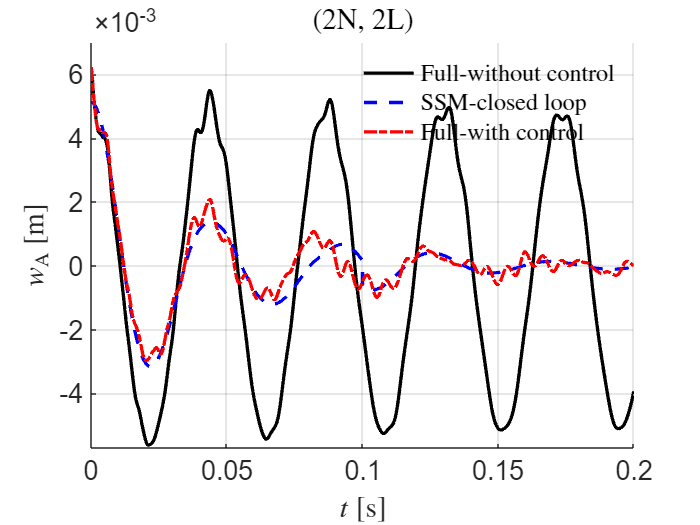

figure; hold on
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot([traj1.time, traj2.time], [traj1.zt(1,:), traj2.zt(1,:)],'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfull1, tfull2], [xfull1(:,1); xfull2(:,1)],'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location='northeast'); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w_\mathrm{A}$ [m]');
ylabel(zk,'Interpreter','latex');
title('(2N, 2L)','Interpreter','latex')
set(gca,'FontSize',16);
grid on
ylim([-0.0057, 0.007])
xlim([0,0.2])

**Plot - control inputs**

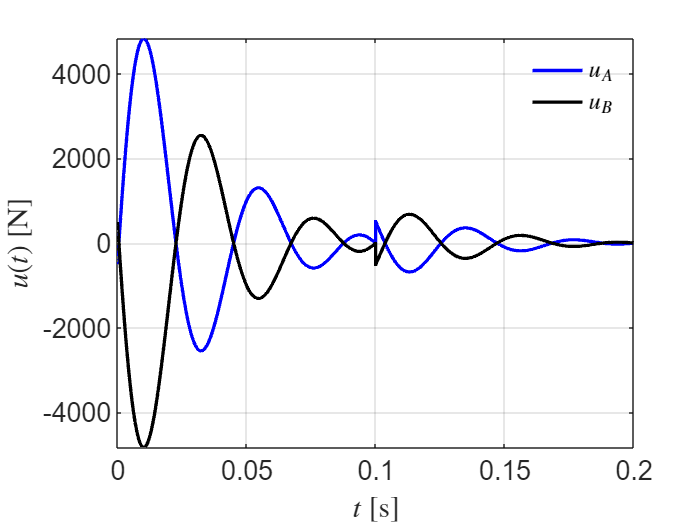

%  control input
figure;
plot([traj1.time, traj2.time],[traj1.ut(1,:), traj2.ut(1,:)],'b-','DisplayName', '$u_A$','LineWidth',2); hold on
plot([traj1.time, traj2.time],[traj1.ut(2,:), traj2.ut(2,:)],'k-','DisplayName', '$u_B$','LineWidth',2); hold on
legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex')
set(gca,'FontSize',16); grid on, axis tight